Assignment 1

% read an image
image = imread('img.jpg')

image = 3770×5306×3 uint8 array
image(:,:,1) =

     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     1     1     2     2     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     2     0     0     0     0     1     1     0     0     0     0    

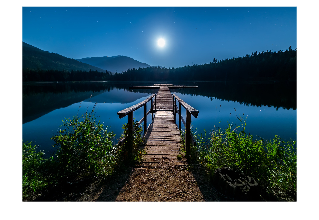

% display the image
imshow(image);

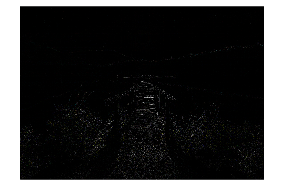

% apply image processing filters to the image
X = fspecial('laplacian',0.2);
Y = fspecial('motion', 100, 120);
final = imfilter(image,X);
% display the result
figure, imshow(final);

% save the result
imwrite(final,'result.png')

 **LAPLACIAN FILTER : **

This filter highlights the edges and detects the transitions of the images which are having sudden intensity.

**MOTION FILTER :**

This filter is used to blur the images according to our requirements based on the given length. 